clearvars
I=imread('cell.tif')

I = 159×191 uint8 matrix
   118   116   112   111   114   118   124   132   162   192   194   180   161   130    95    84    95   124   153   167   168   156   135   116   109   114   121   121   114   105    99    92    95   110   125   127   123   119   108   101   108   123   131   143   164   169   153   133   131   133
   117   119   114   108   110   115   125   152   186   194   183   166   144   112    83    71    75    96   133   160   158   142   123   111   110   116   117   115   109   100    95    97   105   115   126   132   130   121   108   102   111   119   114   113   121   125   121   124   132   130
   115   116   114   108   109   114   135   173   185   170   147   135   127   113    92    76    74    90   126   160   156   132   113   109   108   107   104   107   118   118   109   107   109   113   119   124   123   116   110   113   128   142   142   133   122   107    97   100   112   117
   114   112   108   108   112   121   155   188   182   159   138   131

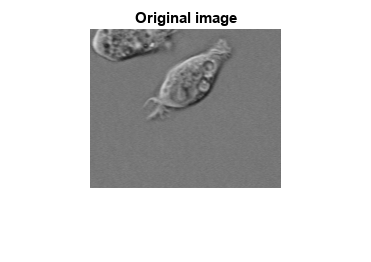

imshow(I)
title('Original image')

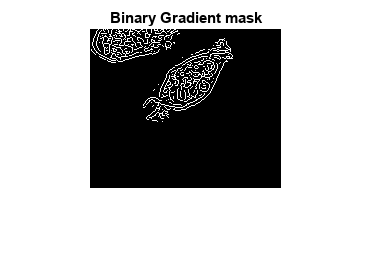

[~,threshold]=edge(I,'sobel');
edgeFactor=0.5;
BWs=edge(I,'sobel',threshold *edgeFactor);
imshow(BWs)
title('Binary Gradient mask')

se90=strel('line',3,90);
se0=strel('line',3,0);

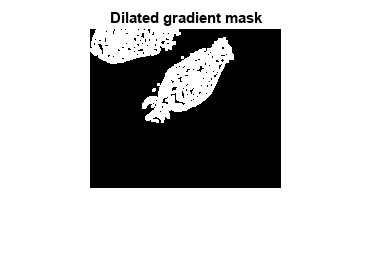

Bwsdil=imdilate(BWs,[se90 se0]);
imshow(Bwsdil)
title('Dilated gradient mask')

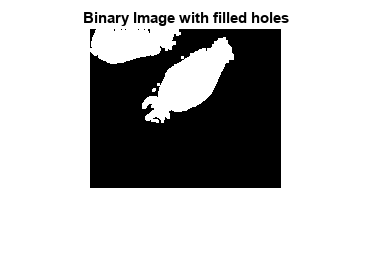

Bwdfill=imfill(Bwsdil,'holes');
imshow(Bwdfill)
title('Binary Image with filled holes')

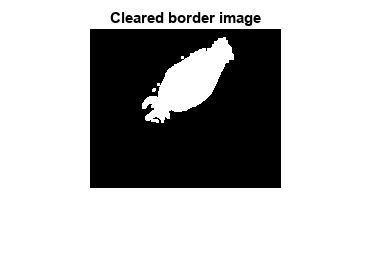

BWnobord=imclearborder(Bwdfill,4);
imshow(BWnobord)
title('Cleared border image')